% linear_multistep_hourly_forecast.m
% -----------------------------------------------------------
% Single linear regression model that predicts hourly load
% for the next 24 hours: y(t+1), y(t+2), ..., y(t+24)
%
% Uses only:
%  - time features (hour/day-of-week via Fourier terms)
%  - weather forecasts for each future hour (Temperature, Humidity)
%
% The script:
%  1) loads the CSV
%  2) builds an hourly dataset (no smoothing; uses on-the-hour samples)
%  3) builds features (time + future weather for 24 horizons)
%  4) constructs multivariate target Y of size N x 24
%  5) splits chronologically into 80% train / 20% test
%  6) fits multivariate linear regression via least-squares
%  7) evaluates and plots results; computes RMSE per horizon
%  8) shows signal-processing diagnostics (autocorr, xcorr)
%
% Important notes (read before using):
% - Training uses *actual future weather* values from the CSV as a
%   proxy for weather forecasts. In deployment replace these with
%   real forecasted weather values for horizons 1..24.
% - The model does NOT use past load as a predictor (per your request).
% -----------------------------------------------------------

clear; close all; clc;

%% -------------------- User settings ------------------------
csvFile = "smart_city_energy_dataset.csv"; % adjust if needed
datetimeColName = "Timestamp";
loadColName     = "Electricity Load";
tempColPattern  = "Temperature";    % matches 'Temperature (Â°C)'
humColPattern   = "Humidity";       % matches 'Humidity (%)'
weatherColPattern = "Weather";      % matches 'Weather Condition' (kept but sparingly used)

H = 24;        % number of hourly horizons to predict (1..24)
trainFrac = 0.80; % chronological split

%% -------------------- Load CSV --------------------------------
fprintf("Loading CSV: %s\n", csvFile);

Loading CSV: smart_city_energy_dataset.csv


T = readtable(csvFile, 'PreserveVariableNames', true);

% Find column names robustly (handle special characters/encoding)
varNames = T.Properties.VariableNames;
dtColIdx = find(contains(varNames, datetimeColName, 'IgnoreCase', true), 1);
loadColIdx = find(contains(varNames, loadColName, 'IgnoreCase', true), 1);
tempColIdx = find(contains(varNames, tempColPattern, 'IgnoreCase', true), 1);
humColIdx  = find(contains(varNames, humColPattern, 'IgnoreCase', true), 1);
weatherColIdx = find(contains(varNames, weatherColPattern, 'IgnoreCase', true), 1);

if isempty(dtColIdx) || isempty(loadColIdx)
    error("Couldn't find required columns. Check column names in the CSV.");
end

% Extract needed columns
dtRaw = T{:, dtColIdx};
yRaw  = T{:, loadColIdx};

% Convert timestamp to datetime if needed
if ~isdatetime(dtRaw)
    try
        dt = datetime(dtRaw, 'InputFormat', '', 'Locale','en_US'); % auto-detect
    catch
        dt = datetime(dtRaw); % fallback
    end
else
    dt = dtRaw;
end

% Ensure ascending time order
[dt, sortIdx] = sort(dt);
yRaw = yRaw(sortIdx);
if ~isempty(tempColIdx); tempRaw = T{sortIdx, tempColIdx}; else tempRaw = []; end
if ~isempty(humColIdx);  humRaw  = T{sortIdx, humColIdx};  else humRaw = []; end
if ~isempty(weatherColIdx); weatherRaw = T{sortIdx, weatherColIdx}; else weatherRaw = []; end

% Print a quick check
fprintf("Total rows read: %d\n", numel(dt));

Total rows read: 72960



%% -------------------- Build hourly timestamps (no smoothing) ------------
% Your CSV is 30-min. We will choose the samples that fall exactly on the hour
% (minute == 0). If those do not exist (rare), we fall back to taking every
% 2nd sample starting at the first row.

mins = minute(dt);
hourlyMask = (mins == 0);

if sum(hourlyMask) < 10
    fprintf("Less than 10 on-the-hour samples found; falling back to every-2nd sample.\n");
    hourlyIdx = 1:2:length(dt);
else
    hourlyIdx = find(hourlyMask);
end

t_hourly = dt(hourlyIdx);
y_hourly = yRaw(hourlyIdx);
if ~isempty(tempRaw); temp_hourly = tempRaw(hourlyIdx); else temp_hourly = []; end
if ~isempty(humRaw);  hum_hourly  = humRaw(hourlyIdx);  else hum_hourly  = []; end
if ~isempty(weatherRaw); weather_hourly = weatherRaw(hourlyIdx); else weather_hourly = []; end

N = numel(t_hourly);
fprintf("Hourly samples available: %d\n", N);

Hourly samples available: 36480



%% -------------------- Create supervised dataset ------------------------
% For every time index i, we want:
%  X(i,:) = features available at time t_i (time features) + the
%           weather forecasts for horizons 1..H: temp(t_i+1..t_i+H), hum(...)
%  Y(i,:) = [ load(t_i+1), load(t_i+2), ..., load(t_i+H) ]
%
% We can only create samples when i+H <= N.

maxStart = N - H;
if maxStart < 10
    error("Not enough hourly samples to create H=%d horizon samples. Need more data.", H);
end

% Pre-allocate
% Basic time features: sin/cos of hour-of-day and week-of-year -> 4 features
% Future weather: 2 * H features (temperature & humidity at each future hour)
timeFeatCount = 4;
weatherFeatCount = 0;
useTemp = ~isempty(temp_hourly);
useHum  = ~isempty(hum_hourly);

if useTemp, weatherFeatCount = weatherFeatCount + H; end
if useHum,  weatherFeatCount = weatherFeatCount + H; end

P = 1 + timeFeatCount + weatherFeatCount; % +1 for intercept
X = zeros(maxStart, P);
Y = zeros(maxStart, H);

% Helper: compute Fourier features for an hour index
% period1 = 24 (daily), period2 = 24*7 (weekly)
for i = 1:maxStart
    t0 = t_hourly(i);
    % --- time features at reference time t0 ---
    hourOfDay = hour(t0); % 0..23
    % daily Fourier (1 harmonic)
    X(i,2) = sin(2*pi*hourOfDay / 24);
    X(i,3) = cos(2*pi*hourOfDay / 24);
    % weekly feature: use day-of-week + hour to get a fractional "hour of week"
    hourOfWeek = weekday(t0,'long') ; % not numeric fractional; better compute as:
    % compute hour index within the week as (weekday-1)*24 + hour
    dow = day(t0,'dayofweek'); % 1=Sun...7=Sat
    hourOfWeekNum = (dow-1)*24 + hourOfDay; % 0..167
    X(i,4) = sin(2*pi*hourOfWeekNum / (24*7));
    X(i,5) = cos(2*pi*hourOfWeekNum / (24*7));
    % intercept
    X(i,1) = 1;
    % --- weather forecasts for horizons 1..H ---
    col = 1 + timeFeatCount + 1; % starting column for weather (1-based)
    % For each horizon j, get index i+j
    for j = 1:H
        idx = i + j;
        if useTemp
            X(i, col) = temp_hourly(idx);
            col = col + 1;
        end
        if useHum
            X(i, col) = hum_hourly(idx);
            col = col + 1;
        end
    end
    % --- Y: future loads for horizons 1..H ---
    Y(i, :) = y_hourly(i+1 : i+H).';
end

% Remove any rows with NaNs (if weather missing at some future points)
okRows = all(~isnan(X),2) & all(~isnan(Y),2);
X = X(okRows, :);
Y = Y(okRows, :);
nSamples = size(X,1);
fprintf("Created %d supervised samples (after removing NaNs).\n", nSamples);

Created 36456 supervised samples (after removing NaNs).



%% -------------------- Chronological train/test split ---------------------
nTrain = floor(trainFrac * nSamples);
Xtrain = X(1:nTrain, :);
Ytrain = Y(1:nTrain, :);
Xtest  = X(nTrain+1:end, :);
Ytest  = Y(nTrain+1:end, :);

fprintf("Train samples: %d, Test samples: %d\n", size(Xtrain,1), size(Xtest,1));

Train samples: 29164, Test samples: 7292



%% -------------------- Fit multivariate linear regression -------------
% Solve for B (P x H) in least-squares sense: Xtrain * B ≈ Ytrain
% Using backslash solves normal equations (efficient for many outputs)
B = Xtrain \ Ytrain;   % P x H

% Save the model coefficients and metadata
model.B = B;
model.P = P;
model.H = H;
model.featureInfo = struct('useTemp', useTemp, 'useHum', useHum, ...
    'timeFeatCount', timeFeatCount, 'weatherFeatCount', weatherFeatCount);
fprintf("Model training complete. Coefficient matrix size: %dx%d\n", size(B,1), size(B,2));

Model training complete. Coefficient matrix size: 53x24



%% -------------------- Predict on test set -----------------------------
Ypred = Xtest * B;   % (nTest x H)

% Compute RMSE per horizon
nTest = size(Ytest,1);
rmse = sqrt(mean((Ytest - Ypred).^2, 1)); % 1xH

% Summarize RMSE for horizon 1, 6, 12, 24
fprintf("RMSE (hour ahead):\n");

RMSE (hour ahead):


fprintf("  1-hour ahead : %.3f\n", rmse(1));

  1-hour ahead : 261.774


fprintf("  6-hour ahead : %.3f\n", rmse(6));

  6-hour ahead : 261.544


fprintf(" 12-hour ahead : %.3f\n", rmse(12));

 12-hour ahead : 261.546


fprintf(" 24-hour ahead : %.3f\n", rmse(24));

 24-hour ahead : 261.479


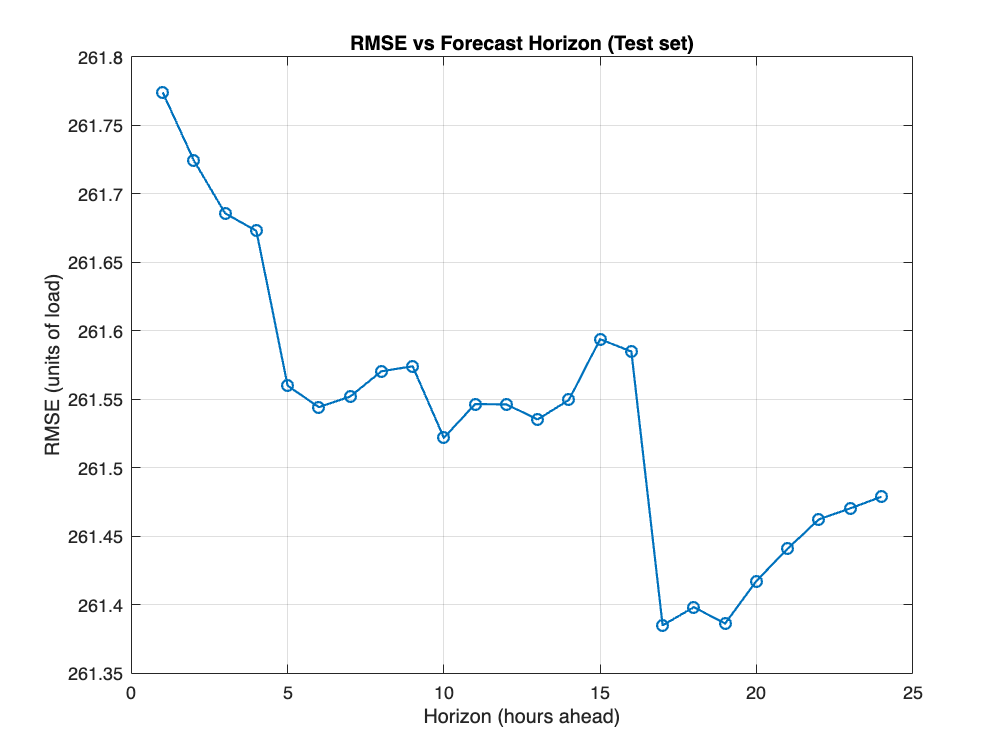


% Plot RMSE across horizons
figure;
plot(1:H, rmse, '-o', 'LineWidth', 1.2);
xlabel('Horizon (hours ahead)');
ylabel('RMSE (units of load)');
title('RMSE vs Forecast Horizon (Test set)');
grid on;

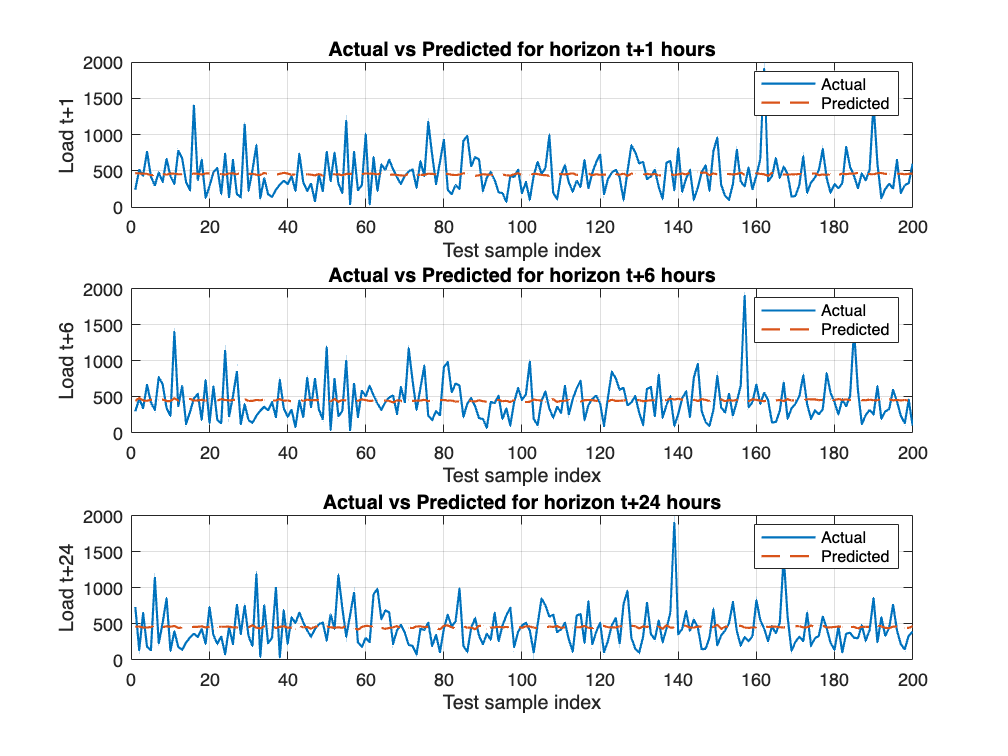


%% -------------------- Example: Actual vs Predicted time-series plots ---
% Pick a test-slice to plot (first 200 test samples or less)
plotLen = min(200, nTest);
t_test_idxStart = nTrain + 1; % index in original supervised samples
% Map testing supervised sample i -> timestamp: t_hourly(originalIndex + i -1)
% Need original mapping: we built supervised samples from hourlyIdx(1:maxStart)
% So to keep things simple, we will show predictions vs actual for 3 horizons:
hPlot = [1, 6, 24];

figure;
for k = 1:numel(hPlot)
    h = hPlot(k);
    subplot(numel(hPlot),1,k);
    plot(1:plotLen, Ytest(1:plotLen,h), '-', 'LineWidth', 1.2);
    hold on;
    plot(1:plotLen, Ypred(1:plotLen,h), '--', 'LineWidth', 1.2);
    legend('Actual','Predicted');
    xlabel('Test sample index');
    ylabel(sprintf('Load t+%d', h));
    title(sprintf('Actual vs Predicted for horizon t+%d hours', h));
    grid on;
end


%% -------------------- Signal-processing diagnostics --------------------
% 1) Autocorrelation of the hourly load (show core SP idea)
figure;
maxLag = 48;
[acf, lags, bounds] = autocorr(y_hourly, 'NumLags', maxLag);

autocorr requires Econometrics Toolbox.

subplot(2,1,1);
stem(0:maxLag, acf, 'filled');
xlabel('Lag (hours)');
ylabel('ACF');
title('Autocorrelation of hourly load (ACF)');

% 2) Cross-correlation between load and temperature (show lead/lag)
if useTemp
    subplot(2,1,2);
    % Use xcorr and show lags in hours (max 48)
    maxLagCorr = 48;
    [xc, lagsxc] = xcorr(zscore(y_hourly(1:end-maxLagCorr)), zscore(temp_hourly(1:end-maxLagCorr)), maxLagCorr, 'coeff');
    stem(lagsxc, xc, 'filled');
    xlabel('Lag (hours)  [positive = temp leads load]');
    ylabel('Cross-corr');
    title('Cross-correlation: load vs temperature');
    grid on;
end

%% -------------------- Feature importance (coefficients) ----------------
% Because this is linear regression, coefficients in B directly show
% influence on each horizon. We'll show coefficients for 1-hour and 24-hour.
coef1 = B(:,1);   % coefficients mapping X -> y(t+1)
coef24 = B(:,24); % mapping X -> y(t+24)

% Create labels for features
featLabels = cell(P,1);
featLabels{1} = 'Intercept';
featLabels{2} = 'sin(hour)';
featLabels{3} = 'cos(hour)';
featLabels{4} = 'sin(hourOfWeek)';
featLabels{5} = 'cos(hourOfWeek)';
col = 6;
for j = 1:H
    if useTemp
        featLabels{col} = sprintf('Temp(t+%d)', j); col = col + 1;
    end
    if useHum
        featLabels{col} = sprintf('Hum(t+%d)', j);  col = col + 1;
    end
end

% Plot coefficient magnitudes for horizon 1 and 24
figure;
subplot(2,1,1);
bar(coef1);
set(gca, 'XTick', 1:P, 'XTickLabel', featLabels, 'XTickLabelRotation', 45);
title('Model coefficients -> y(t+1)');
ylabel('Coefficient value');

subplot(2,1,2);
bar(coef24);
set(gca, 'XTick', 1:P, 'XTickLabel', featLabels, 'XTickLabelRotation', 45);
title('Model coefficients -> y(t+24)');
ylabel('Coefficient value');

%% -------------------- Save model and results -----------------------------
save('linear_multistep_model.mat', 'model', 'B', 'rmse', 'featLabels');

fprintf("Model and figures created. Model saved to linear_multistep_model.mat\n");
fprintf("Notes:\n");
fprintf(" - During deployment, you must provide weather forecasts for horizons 1..24\n");
fprintf("   (temperature and humidity) to create X features for prediction.\n");
fprintf(" - This model does NOT use past loads; if you want to include them\n");
fprintf("   (improves accuracy usually), we can add lag features easily.\n");